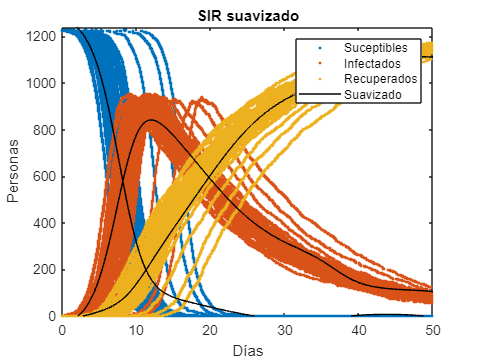

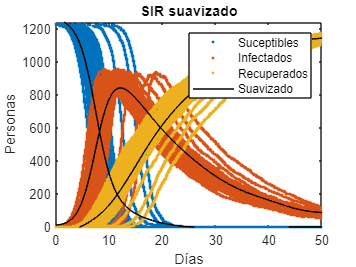

clear all
d=load('reto4.mat');
tiempo=length(d.t);
data=zeros(tiempo,3);
data(:,1)=d.S;
data(:,2)=d.I;
data(:,3)=d.R;
t=zeros(1,tiempo);
t(1,:)=d.t;


% Datos originales y_ruidoso
x = t;  % Valores de tiempo
y_data = data';  % Datos originales (trasponer para que coincidan las dimensiones)

% Crear una red neuronal feedforward
hiddenLayerSize = 5;  % Tamaño de la capa oculta
net = feedforwardnet(hiddenLayerSize);

% Dividir los datos en conjuntos de entrenamiento y prueba (opcional)
% Puedes ajustar esta parte según tus necesidades.
net.trainParam.epochs = 10;
net.divideFcn = 'dividerand';
net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

% Entrenar la red
net = train(net, x, y_data);

% Utilizar la red para predecir los datos suavizados
y_suavizado = net(x);

save('suavizado.mat','y_suavizado');

% Combina las matrices verticalmente
matriz_combinada = vertcat(y_suavizado, x);

% Guarda la matriz combinada en un nuevo archivo
save('matriz_combinada.mat', 'matriz_combinada');

% Trazar las curvas suavizadas
figure;
plot(x,y_data,'.')
hold on
plot(x, y_suavizado,'black');
title('SIR suavizado');
xlim([0 50])
ylim([0 1240])
xlabel('Días');
ylabel('Personas');
legend('Suceptibles','Infectados','Recuperados','Suavizado');